# UFME7R-15-M Robot Learning and Teleoperation Coursework

Report Template: Develop a Method for Single-Arm Robot Manipulation

clearvars

### How do I use this file?

This MLX file should be how you put together your main submission for this coursework. Please read the coursework brief on Blackboard and complete this MLX along with the class files, `SkillGeneralisation.m and` `MixtureGaussian.m` to have a full coursework submission.

Your final submission should consist of this MLX and an exported PDF of this MLX, and your `SkillGeneralisation.m and` `MixtureGaussian.m.` If you are unsure of how to use an MLX, or how to export for submission, please see the guide on Blackboard: [https://blackboard.uwe.ac.uk/bbcswebdav/pid-11024632-dt-content-rid-53216638_2/xid-53216638_2](https://blackboard.uwe.ac.uk/bbcswebdav/pid-11024632-dt-content-rid-53216638_2/xid-53216638_2) 

You should keep all your experimental results and report document within this MLX. However, to make the code work in this MLX, you need to complete some functions in the `SkillGeneralisation.m and` `MixtureGaussian.m` as well. Please read the read the instructions carefully before start your work. If you are proficient with writing MATLAB functions and wish to use them to organise your code, please define them as static functions/methods in `RobotLearning.m` rather than declaring them as separate files. If for some reason this isn't possible, please submit any additional files alongside.

Please also note the following:

- There are some outputs in the template, which are used as reference. Please delete them before you start to add your content.

- Your PDF exported from this MLX will be marked and checked with your completed class files.

- Very wide images do not render well onto the PDF. Please check to make sure images you insert are captured appropriately within the PDF.

## Task 1 (10 Marks)

- Utilise Dynamic Movement Primitives (DMPs) alongside Gaussian Mixture Models (GMM) and Gaussian Mixture Regression (GMR) to devise an enhanced Dynamic Movement Primitives for single-arm robot manipulation.

- During the development of the new algorithm, you can refer to the paper "DMP and GMR based  Teaching by Demonstration for a KUKA LBR Robot" by Hewitt et al., introduced in the reading lecture.

- This paper is included on Blackboard: [https://blackboard.uwe.ac.uk/bbcswebdav/pid-11172103-dt-content-rid-53151419_2/xid-53151419_2](https://blackboard.uwe.ac.uk/bbcswebdav/pid-11172103-dt-content-rid-53151419_2/xid-53151419_2) 

- Write an introduction about the calculation steps based on your understanding of this paper, into your own report.

#### *Useful materials for this Part include:*

- Lecture notes on DMPs: [https://blackboard.uwe.ac.uk/bbcswebdav/pid-11169718-dt-content-rid-53121141_2/xid-53121141_2](https://blackboard.uwe.ac.uk/bbcswebdav/pid-11169718-dt-content-rid-53121141_2/xid-53121141_2) 

- Lecture notes on Linear models: [https://blackboard.uwe.ac.uk/bbcswebdav/pid-11024325-dt-content-rid-52100419_2/xid-52100419_2](https://blackboard.uwe.ac.uk/bbcswebdav/pid-11024325-dt-content-rid-52100419_2/xid-52100419_2) 

- Lecture notes on GMM: [https://blackboard.uwe.ac.uk/bbcswebdav/pid-11065266-dt-content-rid-52179295_2/xid-52179295_2](https://blackboard.uwe.ac.uk/bbcswebdav/pid-11065266-dt-content-rid-52179295_2/xid-52179295_2) 

- Lecture notes on GMR: [https://blackboard.uwe.ac.uk/bbcswebdav/pid-11151991-dt-content-rid-52934847_2/xid-52934847_2](https://blackboard.uwe.ac.uk/bbcswebdav/pid-11151991-dt-content-rid-52934847_2/xid-52934847_2) 

#### Describe your calculations below (max 500 words):

--------------------------------------------------------

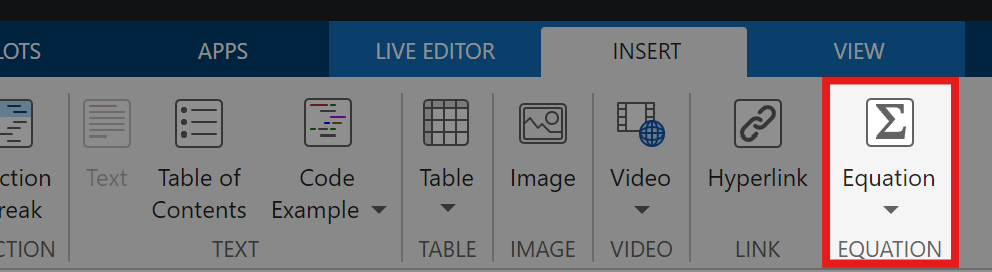

You can use Equation in INSERT tab to write equations in math mode. 

e.g. $y=m\cdot x+c$

--------------------------------------------------------

## Task 2 (50 marks)

Implement your improved DMP method using the following steps:

### Part 1 (15 marks): 

- Employ the original DMP to compute the values of nonlinear term (the forcing term) of the inputs.

#### *Useful materials for this Part include:*

- Lecture notes on DMPs: [https://blackboard.uwe.ac.uk/bbcswebdav/pid-11169718-dt-content-rid-53121141_2/xid-53121141_2](https://blackboard.uwe.ac.uk/bbcswebdav/pid-11169718-dt-content-rid-53121141_2/xid-53121141_2) 

- Code examples for DMPs: [https://blackboard.uwe.ac.uk/webapps/blackboard/content/listContentEditable.jsp?content_id=_11169981_1&course_id=_365949_1](https://blackboard.uwe.ac.uk/webapps/blackboard/content/listContentEditable.jsp?content_id=_11169981_1&course_id=_365949_1) 

- Documentation for loading data into MATLAB: [https://uk.mathworks.com/help/matlab/ref/load.html](https://uk.mathworks.com/help/matlab/ref/load.html) 

The below code provides a starting point for Part 1. You need to complete the functions in the `SkillGeneralisation.m` to make the code work.

Dataset parameters

nbData = 200;               % Length of each demo trajectory 
nbDemos = 5;                % Number of demonstrations for the DMP training

Define DMP parameters

nStates = 9;                % Number of activation functions (i.e., number of states in the forcing term)
nVar = 3;                   % Number of variables [s,f1,f2] (decay term and perturbing force)
beta = 50;                  % Stiffness gain (β)
alpha = (2*beta)^.3;        % Damping gain (with ideal underdamped damping ratio) (α)
decayFactor = 1.1;          % Decay factor (a in τx'=-ax)
dt = 0.01;                  % Duration of time step (τ)

Load handwriting trajectories

demos = [];
load('G.mat');
demos_in = {demos{1:nbDemos}};

Initialise the DMP instance

dmp = SkillGeneralisation(nVar, nStates, beta, alpha, dt);   % Class constructor
dmp = dmp.canonicalSystemInitialisation(decayFactor, nbData);
dmp = dmp.trajectort2Forcing(demos_in);

Regression with Locally Weighted Linear Regression (WLR)

fWLR = dmp.fittingWithLocallyWLS();
trajWLR = dmp.forcing2Trajectory(fWLR);

Spatial plot

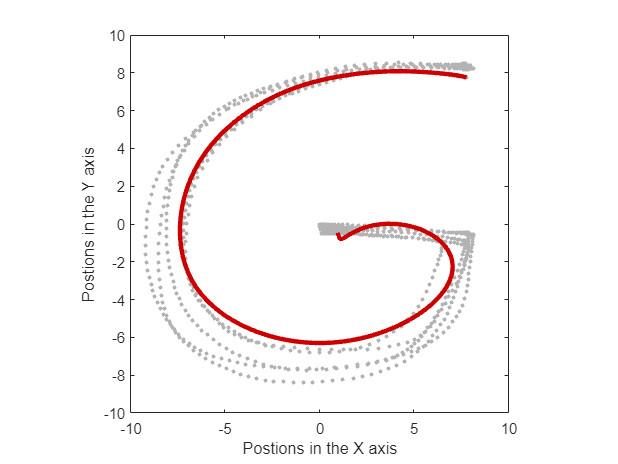

figure,
for n = 1:nbDemos
    plot(demos_in{n}.pos(1,:), demos_in{n}.pos(2,:),'.','markersize',8,'color',[.7 .7 .7]); hold on
end
plot(trajWLR(1,:),trajWLR(2,:),'-','linewidth',3,'color',[.8 0 0]);
xlabel('Postions in the X axis')
ylabel('Postions in the Y axis')
axis equal; axis square; 

### Part 2 (15 marks):

- Utilize Gaussian Mixture Models (GMM) and Gaussian Mixture Regression (GMR) instead of conventional Locally Weighted Linear Regression (WLR) to calculate the trajectory.

#### *Useful materials for this Part include:*

- Lecture notes on GMM: [https://blackboard.uwe.ac.uk/bbcswebdav/pid-11065266-dt-content-rid-52179295_2/xid-52179295_2](https://blackboard.uwe.ac.uk/bbcswebdav/pid-11065266-dt-content-rid-52179295_2/xid-52179295_2) 

- Lecture notes on GMR: [https://blackboard.uwe.ac.uk/bbcswebdav/pid-11151991-dt-content-rid-52934847_2/xid-52934847_2](https://blackboard.uwe.ac.uk/bbcswebdav/pid-11151991-dt-content-rid-52934847_2/xid-52934847_2) 

- Lab tutorial notes on GMM: [https://blackboard.uwe.ac.uk/webapps/blackboard/content/listContentEditable.jsp?content_id=_11071979_1&course_id=_365949_1](https://blackboard.uwe.ac.uk/webapps/blackboard/content/listContentEditable.jsp?content_id=_11071979_1&course_id=_365949_1)

- Lab tutorial notes on GMR: [https://blackboard.uwe.ac.uk/webapps/blackboard/content/listContentEditable.jsp?content_id=_11151988_1&course_id=_365949_1](https://blackboard.uwe.ac.uk/webapps/blackboard/content/listContentEditable.jsp?content_id=_11151988_1&course_id=_365949_1)  

The below code provides a starting point for Part 2. You need to complete the functions in the `MixtureGaussian.m` to make the code work.

fGMR = dmp.fittingWithGMR();
trajGMR = dmp.forcing2Trajectory(fGMR);

Spatial plot

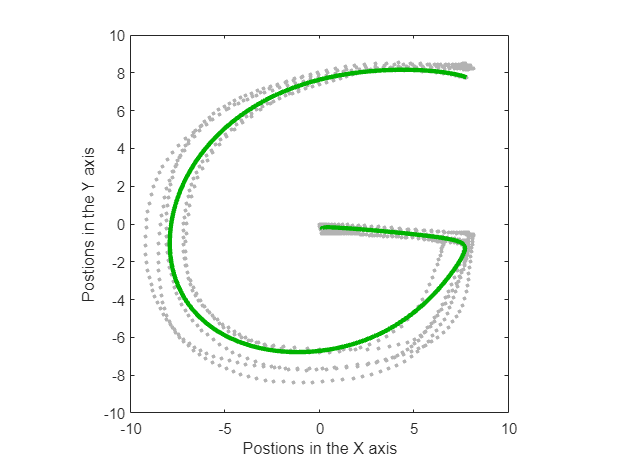

figure,
for n = 1:nbDemos
    plot(demos_in{n}.pos(1,:), demos_in{n}.pos(2,:),'.','markersize',8,'color',[.7 .7 .7]); hold on
end
plot(trajGMR(1,:),trajGMR(2,:),'-','linewidth',3,'color',[0 .7 0]);
xlabel('Postions in the X axis')
ylabel('Postions in the Y axis')
axis equal; axis square; hold off

### Part 3 (5 marks):

- Once the new trajectory has been learned and generalized, save the data in a .mat  format to the workspace

#### *Useful materials for this Part include:*

- The save function documentation: [Save variables from workspace to file - MATLAB save - MathWorks United Kingdom](https://uk.mathworks.com/help/matlab/ref/save.html)

% Add code to generate and save your results here. Please only save the
% relevant variables, not the entire workspace


### **Part 4** (15 marks):

- During teleoperation simulation, load the saved data as inputs for the teleoperation system to facilitate further simulation.

- Please complete simulations and make a screenshot of the simulation results with the scopes to illustrate the simulation results

- Be sure to save your data from Simulink with the filename 'SimOut.mat'

#### ***Useful materials for this Part include:***

- The lecture material on Robot Control

% Add any external code to run the teleoperation simulation here, if required
% Ensure your Simulink model loads and is visible for review


------------------------------------------------------

Add screenshots supporting your results here

-----------------------------------------------------

## Task 3 (15 marks)

- Evaluate the proposed enhanced Dynamic Movement Primitives method by comparing the differences between the original Dynamic Movement Primitives and the enhanced method in Cartesian space coordinates.

- The successful results should demonstrate comparative errors between two different methods.

- Complete the comparison, writing (static) functions in the `RobotLearning.m` or your code here to quantify and compare your results.

- Describe and analyse these results.

Below is a loop to generate an appropriate figure to view your results. Use this as a starting point to demonstrate the differences between original and enhanced DMPs (which you explored in Tasks 1 and 2 respectively).

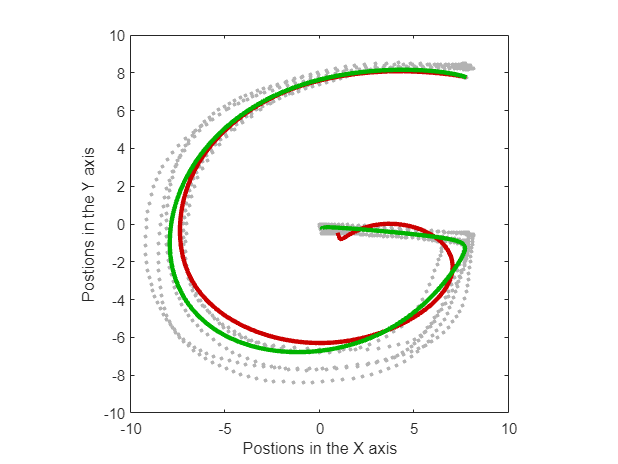

figure,
for n = 1:nbDemos
    plot(demos_in{n}.pos(1,:), demos_in{n}.pos(2,:),'.','markersize',8,'color',[.7 .7 .7]); hold on
end
plot(trajWLR(1,:),trajWLR(2,:),'-','linewidth',3,'color',[.8 0 0]);
plot(trajGMR(1,:),trajGMR(2,:),'-','linewidth',3,'color',[0 .7 0]);
xlabel('Postions in the X axis')
ylabel('Postions in the Y axis')
axis equal; axis square; hold off

#### Describe your results below, comparing the trajectories generated by original vs improved DMPs (max. 500 words):

--------------------------------------------------------

Add your text here

--------------------------------------------------------

## Task 4 (15 marks):

- Save the outputs of the robot learning task above, and load them into the teleoperation model in Simulink

- These outputs should become the inputs on the leader controller side to guide the movement of the follower.

- Design PD or other controllers for both the leader and follower; a good implementation will cause the follower's motions to mirror those of the leader.

- Save and plot the positions on both the leader and follower sides

- Use these plots in your written analysis; compare the trajectories and discuss disparities between them. 

- The control diagram built in Simulink should be included as a screenshot.

% This is the example of drawing a image to analyse the results of the PD control
load('SimOut.mat')

错误使用 load
找不到文件或目录 'SimOut.mat'。

Time = out.tout';
figure,
Joint1 = out.joint.data(:,1); 
Joint2 = out.joint.data(:,2); 
Joint3 = out.joint.data(:,3); 
Joint4 = out.joint.data(:,4);
plot(Time,Joint1); hold on; plot(Time,Joint2); hold on
plot(Time,Joint3); hold on; plot(Time,Joint4);
legend('Joint 1 of leader robot','Joint 2 of leader robot',...
    'Joint 1 of follower robot','Joint 2 of follower robot')
xlabel('Time/s');ylabel('Joint/rad')
% please compare the results, such as positions and joints for the results
% generate by DMP and those of the leader and follower robots
figure,
start_pos = 1500; out.pos.data = out.pos.data*20;
Pos1_x = out.pos.data(start_pos:end,1); Pos1_y = out.pos.data(start_pos:end,2); 
Pos2_x = out.pos.data(start_pos:end,3); Pos2_y = out.pos.data(start_pos:end,4);
Pos3_x = out.pos.data(:,5); Pos3_y = out.pos.data(:,6);
plot(Pos1_x-10,Pos1_y); hold on; 
plot(Pos2_x-10,Pos2_y); hold on
plot(Pos3_x-10,Pos3_y); 
legend('Pos of leader robot', 'Pos of follower robot','Demo pos')
xlabel('Postions in the X axis')
ylabel('Postions in the Y axis')

If you have used MATLAB code to write your controller, add it into the code block below:

If instead you have built your controller using Simulink blocks, add a screenshot of the controller below. If you have used subsystems, you may need multiple screenshots:

-------------------------------------------------------

-------------------------------------------------------

#### Describe and compare your results below (max. 500 words):

--------------------------------------------------------

Add your text here

--------------------------------------------------------

## Extra Credit (max. 10 marks)

Complete the above tasks and document them thoroughly, utilising material covered in the taught material and techniques from the literature. For maximum marks, make sure to:

- Where writing is required, you should describe the your approach to each task justified by the task at hand and your knowledge of the subject - why did you do it this way?

- Make a clear, well-supported comparison of the improved method over the general DMPs; is there a significant improvement (yes or no), and what evidence are you using to support this conclusion?

- Improve your evidence by running multiple variants of your models, such as by changing the parameters in Task 2.

- Improve your analysis by modifying the DMP calculations in Task 3 and detailing the effects of these modification.

- You should also illustrate to what extent the improved method can deal with cooperative robot manipulation.

- Evidence of further reading of the DMP literature, details of the methodology used to approach each task, careful analysis of your results and thoughtful conclusions will all attain additional marks.